# 1chだけ条件別にplotの作成

## 1000epochからstandardとdeviantを選択

一人の被験者だけの1チャンネル分の各1010, 1030, 1050条件ごとの平均波形を求める。

まず，trgを使用して1000 epochsの中からstandardとdeviantそれぞれを選ぶ方法。

% trg=zeros(1000,3,4); % (epoch,dev,part)

1000の中にstandardは１，deviantは２が入っている。

一人目の1010条件の場合は，

%--------------- 各条件のstandardとdeviantそれぞれを選ぶ
% 一人目の1010Hzのstandardだけのepochを選ぶ方法。
find(trg(:,1,1)==1) 

ans =      1
     2
     3
     4
     5
     6
     8
    10
    12
    14
    15
    17
    18
    19
    20


size(find(trg(:,1,1)==1) )

ans =    800     1


% 一人目の1010Hzのdeviantだけのepochを選ぶ方法。 
find(trg(:,1,1)==2) 

ans =      7
     9
    11
    13
    16
    28
    35
    38
    48
    50
    52
    60
    63
    65
    77


size(find(trg(:,1,1)==2) )

ans =    200     1


では，一人の被験者だけの1チャンネル分の各1010, 1030, 1050条件ごとの平均波形を求める。

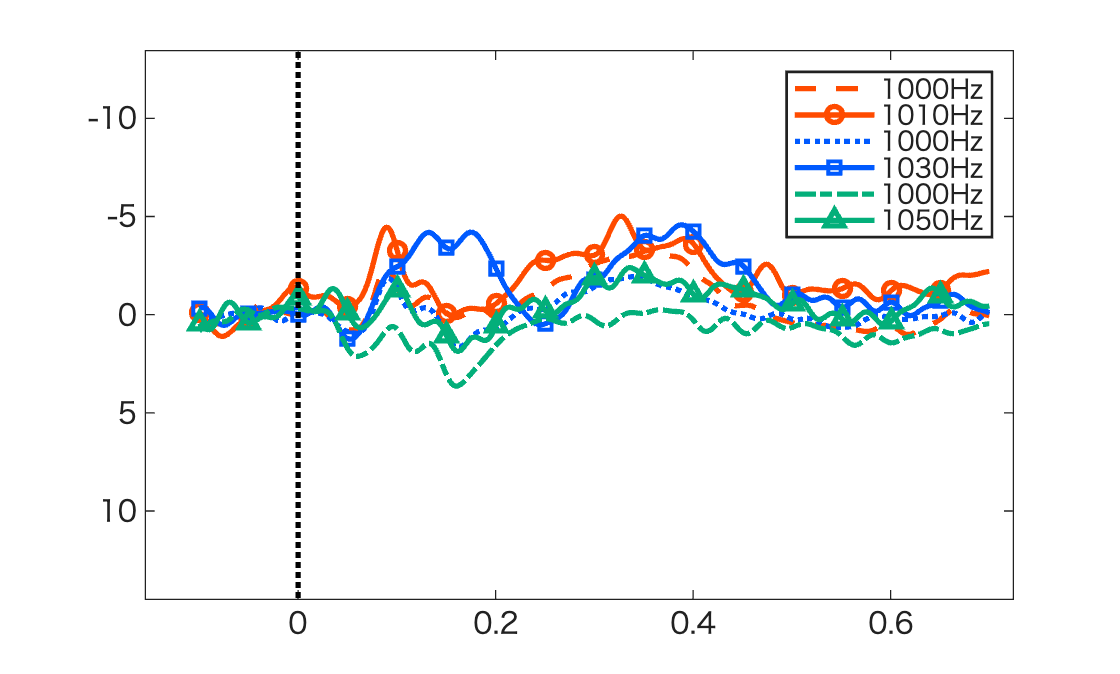

fs = 1000; % サンプリング周波数
N=size(data0,2); % データ長

% ----------trigger
marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
% ----------trigger

% x座標の定義
x=linspace(-0.1,(N-100)/fs,N);

% data->(ch,time,epoch,dev,prt); (31,800,1000,3,X);
    % epoch -> 1:1000
    % dev: 1-> 1010 Hz, 2-> 1030 Hz,  3-> 1050 Hz
    % prt: 
% trg -> (epoch,dev,part); (1000,3,X);
    % epoch -> 1:1000までのepochsがある
    % dev: 1010 Hz　-> 1, 1030 Hz -> 2,  1050 Hz -> 3
    % prt: 
    % standard　-> 1, deviant -> 2

%------------------------------------------------ 各条件の平均を求める

%--------------- 平均を求める
% 関数はmeanだけどartifact detectionのところでartifactを含むepochをNaNにしたので
% 関数meanを使って平均するとNaNを返してしまう。
% この場合は，関数meanで（　'omitnan'　）を使う。
% epochの次元を平均するので，...

% data->(ch,time,epoch,dev,prt); (31,800,1000,3,X);
chl=10;
prt=6;
% mean(data, 平均したいdim, 外れ値指定)
y1=mean(data(chl, :, trg(:,1,prt) == 1, 1, prt),3 ,"omitnan"); % 1010Hz % standard
y2=mean(data(chl, :, trg(:,1,prt) == 2, 1, prt),3 ,"omitnan"); % 1010Hz % deviant
y3=mean(data(chl, :, trg(:,2,prt) == 1, 2, prt),3 ,"omitnan"); % 1030Hz % standard
y4=mean(data(chl, :, trg(:,2,prt) == 2, 2, prt),3 ,"omitnan"); % 1030Hz % deviant
y5=mean(data(chl, :, trg(:,3,prt) == 1, 3, prt),3 ,"omitnan"); % 1050Hz % standard
y6=mean(data(chl, :, trg(:,3,prt) == 2, 3, prt),3 ,"omitnan"); % 1050Hz % deviant
%------------------------------------------------ 各条件の平均を求める

figure
hold on % 新しいプロットを追加するときに現在のプロットを保持する
plot(x,y1,'Color', [255  75   0]/255,'LineWidth',2,'LineStyle','--'); % 1000Hz % standard
plot(x,y2,'Color', [255  75   0]/255,'LineWidth',2,'Marker','o','MarkerIndices',1:50:800); % 1010Hz % deviant
plot(x,y3,'Color', [  0  90 255]/255,'LineWidth',2,'LineStyle',':'); % 1000Hz % standard
plot(x,y4,'Color', [  0  90 255]/255,'LineWidth',2,'Marker','s','MarkerIndices',1:50:800); % 1030Hz % deviant
plot(x,y5,'Color', [  3 175 122]/255,'LineWidth',2,'LineStyle','-.'); % 1000Hz % standard
plot(x,y6,'Color', [  3 175 122]/255,'LineWidth',2,'Marker','^','MarkerIndices',1:50:800); % 1050Hz % deviant
axis('ij')
ymx=10;
ylim([-ymx ymx]) % y軸の範囲を定義する
plot(marker(:,1),marker(:,2),'k:','LineWidth',2); % triggerの位置に点線を引く
set(gca,'box','on'); % 図の外枠を付ける
set(gca,'linewidth',1)
legend(['1000Hz'], ['1010Hz'], ['1000Hz'], ['1030Hz'], ['1000Hz'], ['1050Hz']) % グラフへの凡例の追加